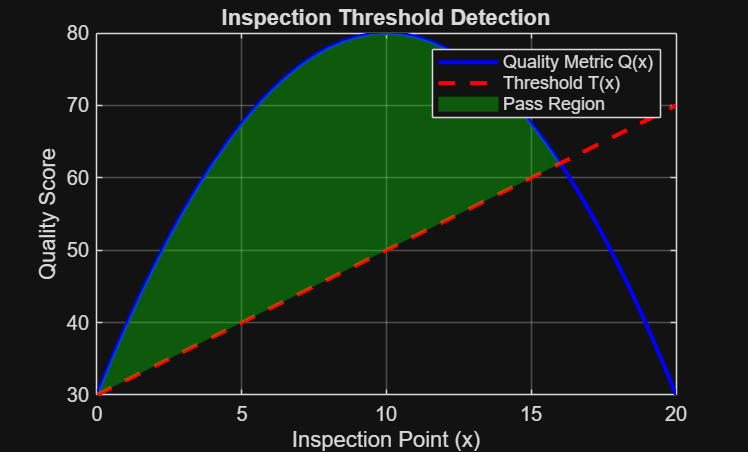

%{
Inspection Threshold Detection (Intersection + Logic)
Author: Diem-Linh Phan
Date: 4-30-2026
Purpose:
    Models a pass/fail quality threshold
Input:
    - N/A:  Function is not expecting arguments.
Output:
    - Graph showing the region that passes the quality inspection 
MATLAB tools/functions:
    - functions
    - plots
    - tables
%}
x = 0 : 0.5 : 20;

% 1 & 2. Define Models
Q = -0.5 * (x - 10).^2 + 80; 
T = 2 * x + 30;              

% 3. intersection
pass_indices = Q >= T;
pass_x = x(pass_indices);

% 4. Plot
figure;
plot(x, Q, 'b-', 'LineWidth', 2); hold on;
plot(x, T, 'r--', 'LineWidth', 2);
grid on;

% Pass Region
fill([pass_x, fliplr(pass_x)], [Q(pass_indices), fliplr(T(pass_indices))], ...
     'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none');

xlabel('Inspection Point (x)');
ylabel('Quality Score');
legend('Quality Metric Q(x)', 'Threshold T(x)', 'Pass Region');
title('Inspection Threshold Detection');


% Output Intervals
if ~isempty(pass_x)
    fprintf('Pass Interval: x = %.1f to %.1f\n', min(pass_x), max(pass_x));
else
    fprintf('No pass intervals found.\n');
end

Pass Interval: x = 0.0 to 16.0
